% Loading data first

%% load the best-fitted parameter sets
bestfit_paramsets = readmatrix('fitted_paramsets_rev2_STEP3.csv');
% note: the first column is the fit score
bestfit_paramsets(:,1) = [];

%% Load the individualised specie values 

init_conditions_table = readtable('initial_conditions.csv','Delimiter',',', 'ReadVariableNames', true');

% simulate first N cell lines and store each outputs in a table 
sim_data = table();
total = height(init_conditions_table);
rng(242, "twister");
random_set = randperm(total,200);
for i = 1:length(random_set)
    k = random_set(i);
    x0s = transpose(table2array(init_conditions_table(k,2:end)));
    cellline = string(init_conditions_table.Var1(k));
    % select a paramset id 
    param_id = 1;
    try
        tbl = run_FGFR4_model(x0s, bestfit_paramsets, param_id, false, "active", "default");
        sim_data = [sim_data; {cellline, tbl}];
    catch exception
        disp(cellline);
        disp(exception);
    end
end 

sim_data.Properties.VariableNames = {'cellline', 'data'};

cellline_legend = {};
for i = 1:200
    cell_data = sim_data(i, "data").data;
    tbl = cell_data{1}; 
    cellline = string(sim_data(i, "cellline").cellline);
    col_data = tbl.pIGFR;
    plot(col_data, 'LineWidth',1)
    cellline_legend = [cellline_legend; cellline];
    hold on 
end

% legend(cellline_legend, "Visible","off");
grid on 
title('pIGFR Time Course of the FGFR4 Model', 'FontSize', 16)
xlabel('Time (Hours)', 'FontSize', 14)
ylabel('Expression', 'FontSize', 14)
hold off

% generation of dynamic features

all_celllines = {};

all_dynamic_features = [];

for i = 1:length(random_set)
    cell_data = sim_data(i, "data").data;
    tbl = cell_data{1}; 
    col_data = tbl.pIGFR;
    cellline = string(sim_data(i, "cellline").cellline);
    dynamic_features = get_dynamic_features(col_data);

    % append new data 
    all_celllines = [all_celllines; cellline];
    all_dynamic_features = [all_dynamic_features; dynamic_features];
end

all_dynamic_features = cell2mat(all_dynamic_features);

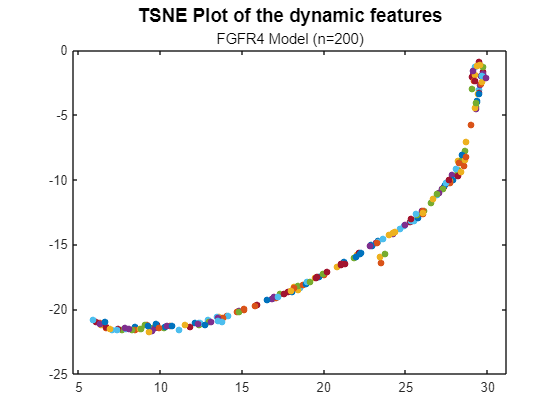

% apply tsne on dynamic features 

rng default
Y = tsne(all_dynamic_features);
gscatter(Y(:,1),Y(:,2),all_celllines)
title('TSNE Plot of the dynamic features', 'FontSize', 14)
subtitle('FGFR4 Model (n=200)')
legend off

opts = statset('Display','final');
[idx,C] = kmeans(Y,2, Options=opts);

Replicate 1, 5 iterations, total sum of distances = 5446.33.
Best total sum of distances = 5446.33


X = Y;
figure;
plot(X(idx==1,1),X(idx==1,2),'r.','MarkerSize',12)
hold on
plot(X(idx==2,1),X(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title('Cluster Assignments and Centroids', 'FontSize', 14)
hold off

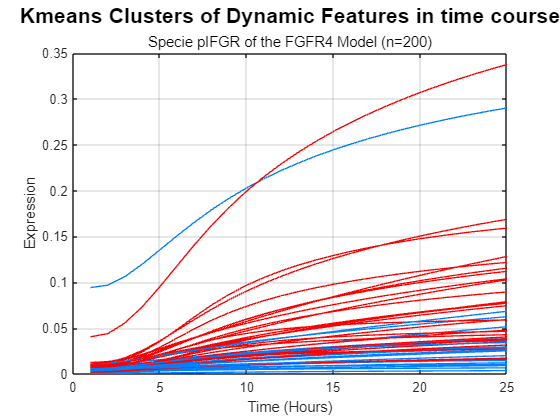

cellline_legend = {};
for i = 1:50 
    cell_data = sim_data(i, "data").data;
    tbl = cell_data{1}; 
    cellline = string(sim_data(i, "cellline").cellline);
    col_data = tbl.pIGFR;
    if idx(i) == 1
        plot(col_data, "Color", [1, 0, 0, 0.1], 'LineWidth', 1);
    elseif idx(i) == 2
        plot(col_data, "Color", [0, 0.5, 1, 0.1], 'LineWidth', 1);
    end 
    cellline_legend = [cellline_legend; cellline];
    hold on 
end

% legend(cellline_legend, "Visible","off");
grid on 
title('Kmeans Clusters of Dynamic Features in time course', 'FontSize', 16)
subtitle('Specie pIFGR of the FGFR4 Model (n=200)')
xlabel('Time (Hours)')
ylabel('Expression')
hold off